addpath('./functions');
addpath('./data');

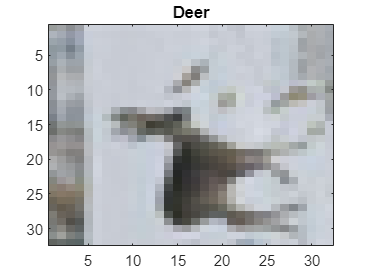

load('data\cifar-10-batches-mat\data_batch_1.mat')

[permutedImageData, categoricalLabels] = permute_dataset(data, labels);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(permutedImageData,1));

imagesc(permutedImageData(:,:,:,idx))
title(label2name(categoricalLabels(idx)))

nomralizedData = normalize_data(permutedImageData);